

% Load simulation data (uncomment if loading from file)
% load('your_simulation_data.mat');

% Extract time and signal data from the structure
time = out.Tuned_Lead_plant_disturbance_noise.time;
signal = out.Tuned_Lead_plant_disturbance_noise.signals.values;

% If multiple signals, select the first one (modify index as needed)
if size(signal, 2) > 1
    signal = signal(:, 1);
    fprintf('Multiple signals detected. Analyzing first signal.\n');
end

% Plot the step response
figure;
plot(time, signal, 'b-', 'LineWidth', 1.5);
grid on;
xlabel('Time (s)');
ylabel('Amplitude');
title('Step Response Analysis');

% Use MATLAB's built-in stepinfo function
% This is much more accurate and handles edge cases properly
info = stepinfo(signal, time);

% Display results
fprintf('\n=== Step Response Performance Metrics (using stepinfo) ===\n');


=== Step Response Performance Metrics (using stepinfo) ===


fprintf('Rise Time:                %.4f seconds\n', info.RiseTime);

Rise Time:                10.7645 seconds


fprintf('Settling Time:            %.4f seconds\n', info.SettlingTime);

Settling Time:            20.1626 seconds


fprintf('Settling Min:             %.4f\n', info.SettlingMin);

Settling Min:             9.0002


fprintf('Settling Max:             %.4f\n', info.SettlingMax);

Settling Max:             9.9999


fprintf('Overshoot:                %.2f%%\n', info.Overshoot);

Overshoot:                0.00%


fprintf('Undershoot:               %.2f%%\n', info.Undershoot);

Undershoot:               -0.00%


fprintf('Peak:                     %.4f\n', info.Peak);

Peak:                     9.9999


fprintf('Peak Time:                %.4f seconds\n', info.PeakTime);

Peak Time:                60.0000 seconds



% Additional calculations
final_value = signal(end);
steady_state_error = abs(1 - final_value);  % Assuming unit step input

fprintf('Final Value:              %.4f\n', final_value);

Final Value:              9.9999


fprintf('Steady-State Error:       %.4f\n', steady_state_error);

Steady-State Error:       8.9999


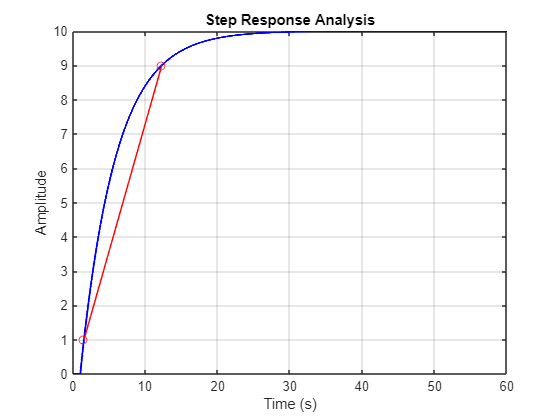


% Add annotations to the plot
hold on;

% Mark rise time region
rise_start_val = info.Peak * 0.1;
rise_end_val = info.Peak * 0.9;
rise_start_idx = find(signal >= rise_start_val, 1, 'first');
rise_end_idx = find(signal >= rise_end_val, 1, 'first');

if ~isempty(rise_start_idx) && ~isempty(rise_end_idx)
    plot([time(rise_start_idx), time(rise_end_idx)], ...
         [rise_start_val, rise_end_val], 'ro-', 'MarkerSize', 6);
end


% Mark settling band
settling_upper = info.SettlingMax;
settling_lower = info.SettlingMin;
plot([0, time(end)], [settling_upper, settling_upper], 'r--', 'Alpha', 0.7);

Error using plot
Unrecognized property Alpha for class Line.

plot([0, time(end)], [settling_lower, settling_lower], 'r--', 'Alpha', 0.7);

% Mark peak
plot(info.PeakTime, info.Peak, 'gs', 'MarkerSize', 8, 'MarkerFaceColor', 'g');

legend('Step Response', 'Rise Time', 'Settling Band', '', 'Peak', 'Location', 'best');
hold off;

% Store all information in a comprehensive structure
metrics = info;  % All stepinfo results
metrics.FinalValue = final_value;
metrics.SteadyStateError = steady_state_error;

fprintf('\nAll metrics saved to ''metrics'' structure.\n');
fprintf('Use ''metrics'' to access individual values (e.g., metrics.RiseTime)\n');

% Optional: Display the structure fields
fprintf('\nAvailable metrics fields:\n');
disp(fieldnames(metrics));